clear
[test_data, test_name] = Extract_short('Recording','Test_Recording',1);
[train_data, train_name] = Extract_short('Recording','Train_Recording',1);
[free_data, free_name] = Extract_short('Recording','Free_Recording',1);

fs = 48000;
% sound(train_data(:,2),fs) 

train_data_fft= [] ;
for count = 1:48
    train_data_fft(:,count) = fftshift(fft(train_data(:,count)));
end
test_data_fft= [] ;
for count = 1:24
    test_data_fft(:,count) = fftshift(fft(test_data(:,count)));
end
free_data_fft= [] ;
for count = 1:25
    free_data_fft(:,count) = fftshift(fft(free_data(:,count)));
end

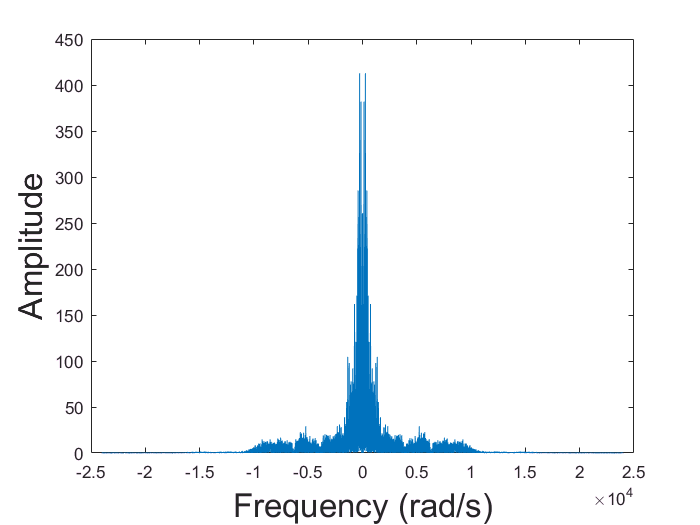

N = length(train_data(:,30));
frequencies = linspace(-fs/2, fs/2-fs/N, N) + fs/(2*N) * mod(N,2);%(linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2))*Fs;
plot(frequencies,abs(train_data_fft(:,30)));
h = xlabel('Frequency (rad/s)');
set(h, 'FontSize',20);
h = ylabel('Amplitude');
set(h, 'FontSize',20);

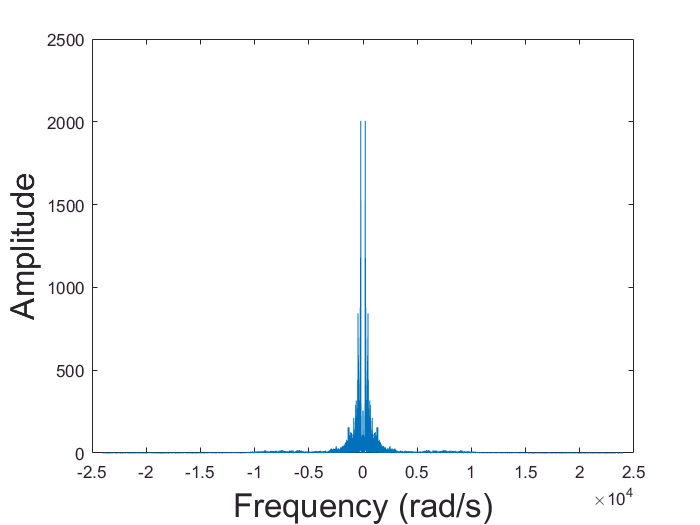

N = length(test_data(:,12));
frequencies = linspace(-fs/2, fs/2-fs/N, N) + fs/(2*N) * mod(N,2);
plot(frequencies,abs(test_data_fft(:,12)));
h = xlabel('Frequency (rad/s)');
set(h, 'FontSize',20);
h = ylabel('Amplitude');
set(h, 'FontSize',20);

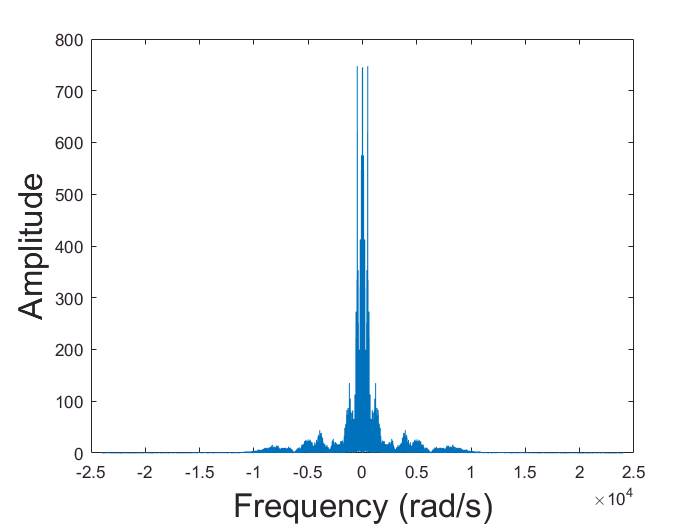

N = length(free_data(:,20));
frequencies = linspace(-fs/2, fs/2-fs/N, N) + fs/(2*N) * mod(N,2);
plot(frequencies,abs(free_data_fft(:,20)));
h = xlabel('Frequency (rad/s)');
set(h, 'FontSize',20);
h = ylabel('Amplitude');
set(h, 'FontSize',20);

mean_img = mean(abs(train_data_fft), 2);
train_data_fft_mean_centered = abs(train_data_fft) - mean_img;
[U,S,V] = svd(train_data_fft_mean_centered, 'econ');

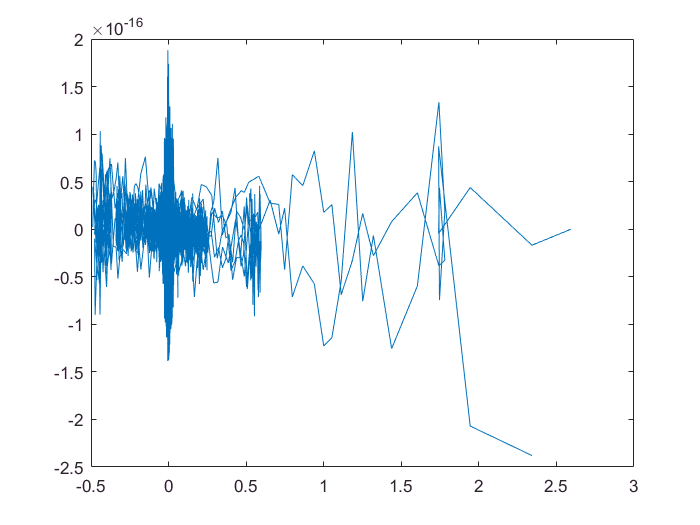

out = ifft(ifftshift(abs(U(:,1)*10000)));
plot(out)

sound(abs(out),fs)

for ind = 1:48
    filename = char(strcat('EigenVoices\eigvoice-',string(ind),'.wav'));
    out = ifft(ifftshift(abs(U(:,ind)*10000)));
    y = out./(max(abs(out)));
    audiowrite(filename,y,fs);
end

eig_vec = U(:,1:15);
training_weights = transpose(eig_vec)*train_data_fft_mean_centered;

correct = 0;
wrong = 0;
guessed = cell(length(test_name),2);
for index = 1:length(test_name)
    sample_img_stacked_mean = abs(test_data_fft(:,index)) - mean_img;
    
    sample_img_weight = transpose(eig_vec)*sample_img_stacked_mean;
    
    dist = sqrt((abs(training_weights - sample_img_weight)));
    sum_dist = sum(dist);
    %subtract sample image weight from training wieghts, use min to find smallest
    %value and get min to return index
    [~,I] = min(sum_dist);
    if test_name{index} == train_name{I}
        correct = correct + 1;
    else
        wrong = wrong+1;
    end
    guessed(index,:) = {test_name{index},train_name{I}};
end
accuracy = (abs(size(test_data_fft,2)-wrong)/size(test_data_fft,2))*100;

index = 4;
sample_img_stacked_mean = abs(free_data_fft(:,index)) - mean_img;

sample_img_weight = transpose(eig_vec)*sample_img_stacked_mean;

dist = sqrt(abs(training_weights - sample_img_weight));
sum_dist = sum(dist);
%subtract sample image weight from training wieghts, use min to find smallest
%value and get min to return index
[M,I] = min(sum_dist);

free_name{index}

ans = "CJ"

train_name{I}

ans = "Utsav"

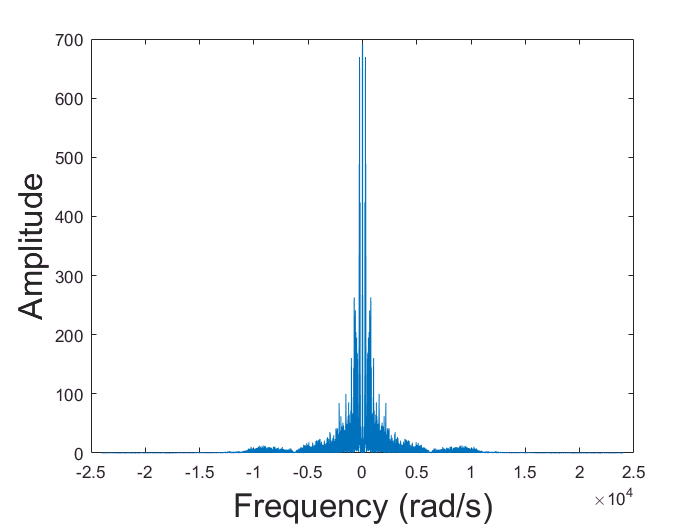

N = length(test_data(:,10));
frequencies = linspace(-fs/2, fs/2-fs/N, N) + fs/(2*N) * mod(N,2);%(linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2))*Fs;
plot(frequencies,abs(test_data_fft(:,10)));
h = xlabel('Frequency (rad/s)');
set(h, 'FontSize',20);
h = ylabel('Amplitude');
set(h, 'FontSize',20);

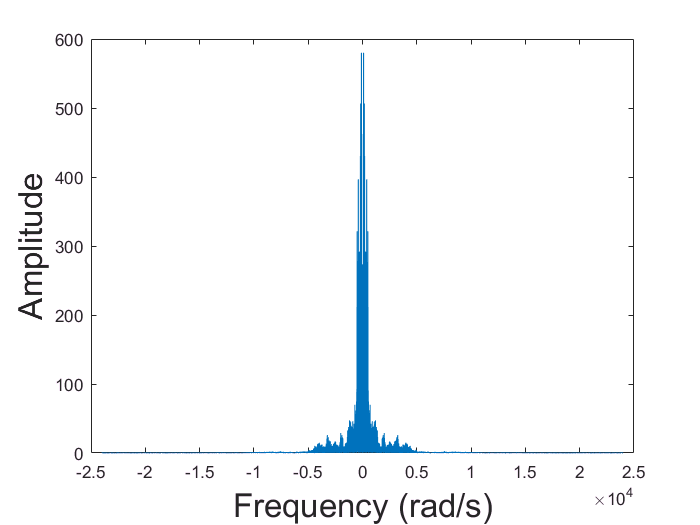


N = length(test_data(:,5));
frequencies = linspace(-fs/2, fs/2-fs/N, N) + fs/(2*N) * mod(N,2);%(linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2))*Fs;
plot(frequencies,abs(test_data_fft(:,5)));
h = xlabel('Frequency (rad/s)');
set(h, 'FontSize',20);
h = ylabel('Amplitude');
set(h, 'FontSize',20);